initialize the robot


robot = exampleHelperMwIiwa14(); 
q = robot.randomConfiguration;

q =    -0.2935   -1.7433   -1.6083    1.7314   -2.0628    1.3648    0.2342


## compute a joint space path for  the master robot  

qi = robot.homeConfiguration;
qdoti=zeros(1,7);
qddoti=zeros(1,7);
qf= robot.randomConfiguration;
qdotf = zeros(1,7);
qddotf = zeros(1,7);

join_space_path = JointPath(qi',qdoti',qddoti',qf',qdotf',qddotf',2,50);

T = linspace(0,2,50);


## fing the task space path for the genrated trajectory.

[n,m]= size(join_space_path);
tspathM = zeros(6,m);
 for i=1:1:m
     tspathM(:,i) = Fk(robot,join_space_path(:,i));
 end

## Object desired trajectory cartesian trajectory

 L=0.7; %lenght of the object
 Pos_o =zeros(6,m); %
  Pos_e =zeros(6,m);
for i=1:1:m
    X =sin(tspathM(4,i))*cos(tspathM(6,i));   % L*sin(alpha)*cos(gamma) X coordinate of the object
    Y =  sin(tspathM(4,i))*sin(tspathM(6,i)); % L*sin(alpha)*sin(gamma) X coordinate of the object
    Z= cos(tspathM(5,i));   
    Pos_o(:,i)=tspathM(:,i)+[X,Y,Z,0,0,0]'*(L/2);  %   object position
     Pos_e(:,i)=tspathM(:,i)+[X,Y,Z,0,0,0]'*L;     %  robot follower position 
end


## plot

ee1=tspathM;
ee2=Pos_e;
obj = Pos_o;

%plot3(ee1(1,:),ee1(2,:),ee1(3,:),'r',obj(1,:),obj(2,:),obj(3,:),'g',ee2(1,:),ee2(2,:),ee2(3,:))


## Jacobian Matrix 

J = robot.geometricJacobian(robot.homeConfiguration,'iiwa_link_ee')

## mass inertia

robot.massMatrix() 

## Control parameters

Kd= eye(7,7)*1000;
Kp=eye(7,7)*800;
Ki = eye(7,7)*1000;

## Desired velocity and acceleration trajectory

Dt= T(2)-T(1);
qd = join_space_path;
qdotd = zeros(n,m); %qdotc =zeros(n,1);
qddotd=zeros(n,m);  %qddotc = zeros(n,1);

for i=2:1:m 
    qdotd(:,i) = (qd(:,i)-qd(:,i-1))/Dt;
    qddotd(:,i) = (qdotd(:,i)-qdotd(:,i-1))/Dt;
end




## Computer torque controller

% time derivative
Dt = T(2)-T(1);
% initial error position
Ep=zeros(7,1); Edotp=zeros(7,1);%Edotc=zeros(7,1);
initial_pos=robot.homeConfiguration;
%error position
computer_pos = zeros(6,m);
errorP = zeros(7,m);
errorV = zeros(7,m);
qc =robot.homeConfiguration;
qdotc=zeros(7,1);
qddotc=zeros(7,1);
Ec = qd(:,1) -qc';
Edotc = qdotd(:,1)-qdotc;
qdotp = qdotc;

for i=1:1:m
    delta = trapz([Ec, Ep],2)*Dt;
    u= qddotd(:,i) + Kd*Edotc + Kp* Ec + Ki*delta;
    % computed torque
    if i==1
      tau = robot.inverseDynamics(qc,qdotc',u');
    else
      tau = robot.inverseDynamics(qc',qdotc',u');
    end
    %ccalculate q and qdot
    joint_acc  =robot.forwardDynamics(tau);
    qdotc = trapz([qddotc,joint_acc'],2)*Dt;
    qc = trapz([qdotp,qdotc],2);
   % pos = Fk(robot, q);
    %computer_pos(:,i) =pos;
    qdotp = qdotc;
    Ec = qd(:,i) -qc;
    Ep = Ec;
    Edotc = qdotd(:,1)-qdotc;
    errorP(:,i)=Ec;
    errorV(:,i)=Edotc;
end


## plot the error

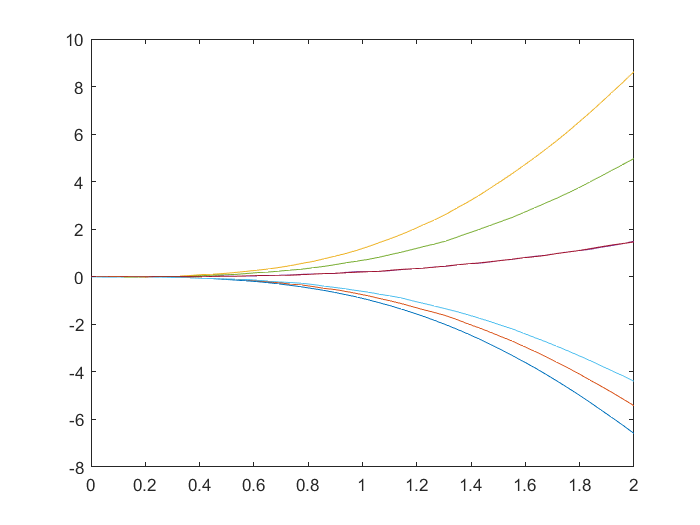

plot(T,errorP)

## code from the main file not ot be execute

 tipHandle = getJointHandle('MasterTip');
     initPoseHandle =  getJointHandle('InitPose');
     finalPoseHandle = getJointHandle('FinalePose');
      %% get the initial and final position in the 
      initPose= getPose(clientID,initPoseHandle);
      finalPose = getPose(clientID,finalPoseHandle);
      trans = getTransform(initPose);
      initConfig = IK('iiwa_link_ee',trans,weights,zeros(7,1));
      
      trans = getTransform(finalPose);
      finalConfig = IK('iiwa_link_ee',trans,weights,zeros(7,1));
      %% generate the desire trajectory path for the master robot
      path = JointPath(initConfig,zeros(7,1),zeros(7,1),finalConfig,zeros(7,1),zeros(7,1),4,20);
      %% follow the path and compute the torque for the follower robot using the inverse dynamic to
    fprintf("error %f signal %d",signal,err);
      for j=1:size(path,2)
          %retrieve and print the joint angles
          % q = getJointAngles(jh);
          
%           q= robot.randomConfiguration;
            joints= path(:,j);
          
            code = setJointAngles(clientID,jh,joints);
            tau = getJointTorques(clientID,jh,j);
            disp(tau);
            pause(1.5);
           %disp(q);disp("\n");
      end